# Part 2: Access and import the data

[*Return to introduction*](matlab: edit S1_Introduction.mlx)

## 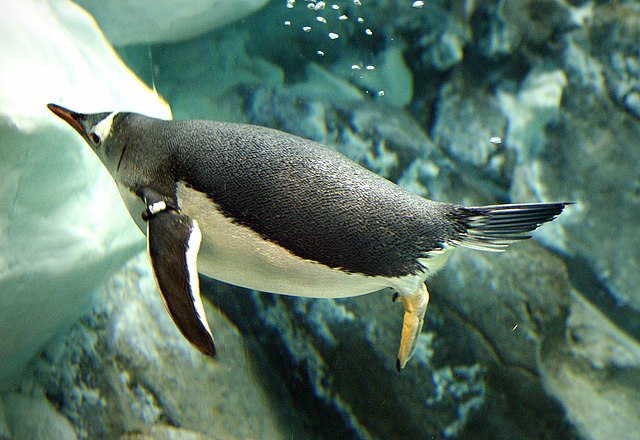

A Gentoo penguin taking a little [swim](https://commons.wikimedia.org/wiki/File:Gentoo_Penguin._(9867788974).jpg). 

## 1: First things first: grab the data

We're going to access this data from GitHub®, which is a place where people can store and share code and data. GitHub allows people to easily collaborate. Rather than emailing files back and forth, you place the files on G, and multiple people can work on them and make changes. GitHub uses version control (called 'git'), which tracks every single change made to the code (including by who and when), so if something goes wrong or breaks, you can easily go back to an earlier version! It's also a great place to store and access data, as we see here. Check out [this article](https://blogs.mathworks.com/matlab/2023/07/20/open-science-and-reusable-research-with-matlab-online-and-github/?s_tid=srchtitle_GitHub_4) on how using GitHub with MATLAB® allows for more open and reproducible science. 

Step 1: [Open the webpage containing the data](https://github.com/mwaskom/seaborn-data/blob/master/penguins.csv)

Step 2: Now you're looking at a GitHub repository that contains this data as a table. On this page, click the **Download raw file **button**. '**penguins.csv' will be saved to your Downloads folder. 

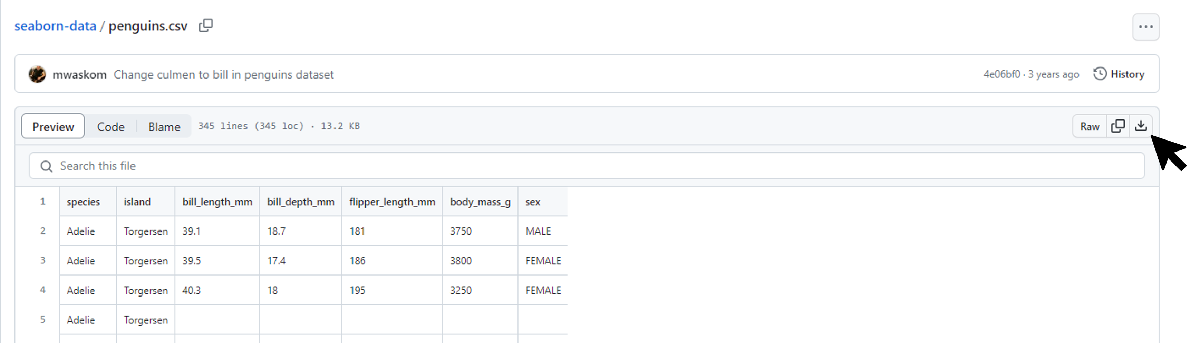

Step 3: Copy and paste this file into the folder these live scripts are saved in: 

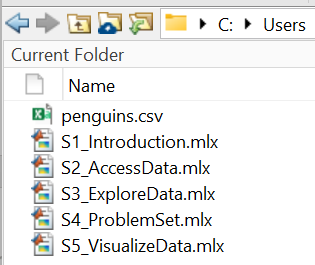

Because this data is in a repository, we can also pull the data directly into MATLAB from git. If you're interested in learning this method, go to this module on [stucturing code](https://www.mathworks.com/matlabcentral/fileexchange/115905-programming-structuring-code) and go through the section on "Sharing Code". 

## 2: How to interact with this live script 

You've got the live script open in MATLAB, and you've got your data in the same folder as your live script, now what the heck do you do with it? All you have to do is read through everything and follow the outlined steps. The only thing you need to learn first is how to run a code block. 

If you see a grey rectangle with code in it that looks something like this, you just need to Navigate to the** Live Editor** tab at the top of your MATLAB window and click the   **Run Section** button. The code inside the block will run, and you should see an output appear below the block.

disp('Hello!')

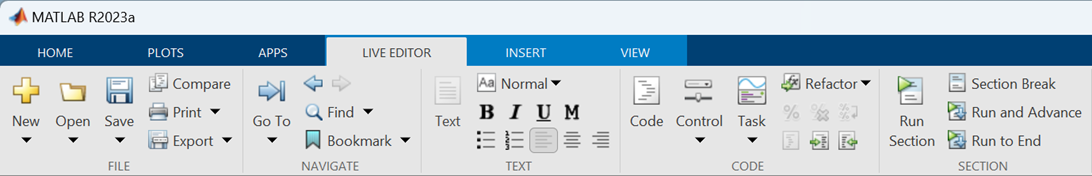

Alternatively, click inside the code block and hit **CTRL** + **ENTER** on your keyboard. 

If you want to get rid of the outputs that have printed and start fresh, go to the **View** tab and select   **Clear all Output**. You can also right-click in the live script and find **Clear Output **(run from a section in the live script to clear just that section but leave other outputs), or **Clear All Output**.

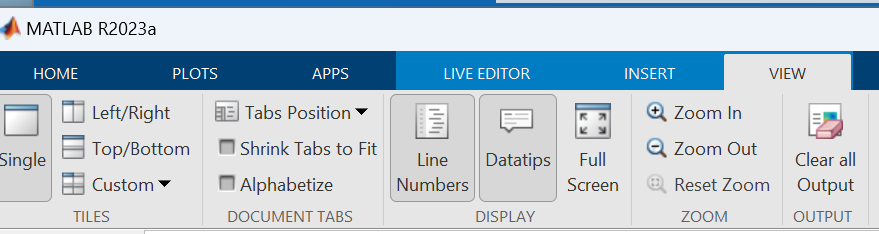

## 3: What to do when you run into trouble 

If you run a code cell and get an error like this line of red code: 

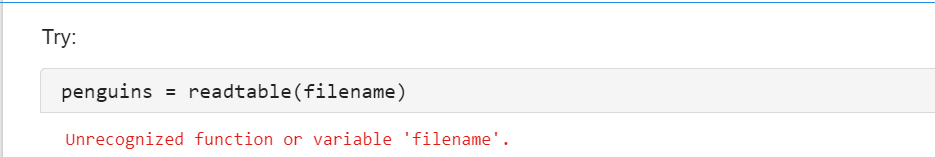

First, make sure you ran all the code blocks above the block you're on. Some of them depend on each other! Second, double check that your Current Folder is correct and has both your current live script and any data you downloaded. These are the two most common culprits when you're working with these live scripts. 

If you are writing your own code and run into issues, MATLAB makes it really easy to debug code ([helpful resource](https://www.mathworks.com/help/matlab/matlab_prog/debugging-process-and-features.html)). For slightly more advanced information on debugging code in MATLAB, check out the **Debugging** section of this [module](https://www.mathworks.com/matlabcentral/fileexchange/115905-programming-structuring-code?focused=1c1da1d0-3985-4e69-8a08-f904ecf9ece0&tab=example). ***Tip*****:** you can always copy and paste your error into a search browser, there is almost always a post explaining what that error means in MATLAB Central Answers. 

## 4: Import `penguins.csv` 

Now you have a file on your computer containing this penguin data! Let's bring it into MATLAB so we can play with it. There are a few ways to do this: via the command window, or via the MATLAB import wizard (check out the video on this in the MATLAB Onramp for more information).

### Method 1: Let MATLAB do the importing for you

Step 1: Under the **Home** tab, select   **Import Data**. 

Step 2: Select `penguins.csv`. The Import Tool will open: 

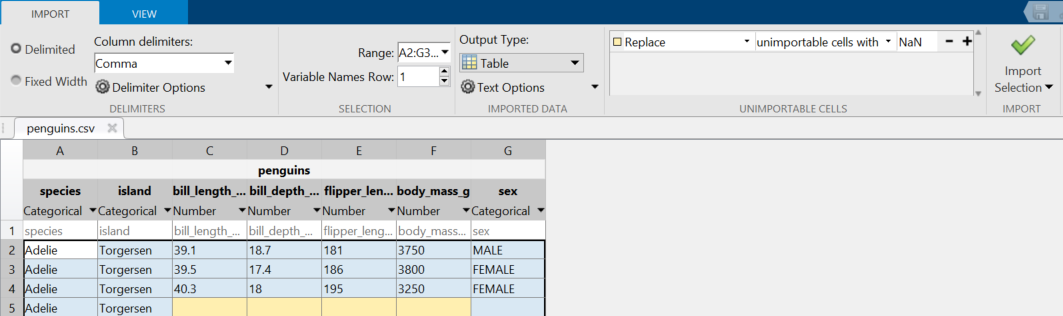

**Note:** The yellow highlight is letting you know which fields of the table are empty. When this data is imported into MATLAB, those fields will be filled with the value "NaN" ("Not a Number") which indicates that the value does not exist. That's ok! Biological datasets are almost never perfect, and learning how to deal with the imperfections is part of the fun. Let's import this. 

Step 3: Click the  **Import Selection** button, followed by **Import Data**. You'll see a variable called `penguins` appear in your workspace. Once you've completed this step, you can close the import tool window.

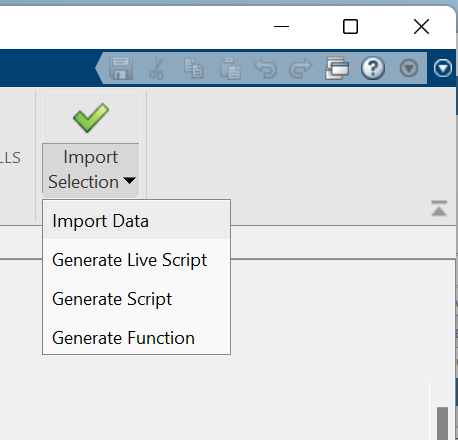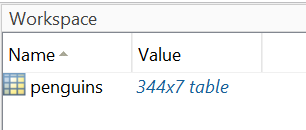 

In the workspace, we can automatically see that `penguins` is a table of size 344 x 7 (meaning we have 344 rows, 7 columns). Each of these rows represents a single penguin and each of the seven columns contains seven different datapoints about each penguin (they tell us about the species of penguin, the island it lives on, the size of its bill (both length and depth), the flipper length, the body mass, and the penguins' sex). So we have really well organized information about each penguin, and throughout this module you'll see how this table structure can be used to help us make interesting observations about these different species of penguins from the Palmer Archipelago. 

That was pretty easy, but what if you wanted to code this yourself?

### Method 2: Try it yourself!

First, we need to tell MATLAB where on the computer to look for your file. We do this by setting a variable to the *path* of the file. (If you're ever unsure of a file's path you can always right-click on a file stored on your computer and click Properties and the path to that file will be listed). We can use a shortcut path if the current folder on the left pane is the folder that our penguins file is saved in. If this is true, we only have to give the name of the file, as opposed to the entire path.

filename = "penguins.csv"; % Put your filename here. 

% By the way, this is a comment! Just type %in any code block to add a
% comment explaining what you are doing-- this makes your code more readable for other people.

Now, we know where on our computer the file lives, so we can next load it into our Workspace. 

Run:

penguins = readtable(filename)

Again, you should see penguins in your workspace. (And, as a bonus, you can see the penguins table populate as the output below the code block. This is simply because we didn't suppress the output of this line of code by putting a semicolon at the end of it). 

  **Try:** see what happens if you add a semicolon to the end of this line!

[`readtable()`](https://www.mathworks.com/help/matlab/ref/readtable.html) is an example of a builtin MATLAB function you can use. This function simply reads spreadsheet data into a table. 

So far, we've loaded our data and stored it as a variable called `penguins`. In the next section, we will explore what we actually have to work with in our dataset. 

[*Go to next script (Explore Data)*](matlab: edit S3_ExploreData.mlx)

[*Return to introduction*](matlab: edit S1_Introduction.mlx)